# Local Planner Simulation

## function import

addpath("./env/");
addpath("./env/map/");
addpath("./utils/");
addpath("./local_planner/");
addpath("./animation/");

## initialize

clear all;
clc;

% load environment
load("gridmap_20x20_scene1.mat");
map_size = size(grid_map);
G = 1;

% start and goal pose
start = [3, 2, 0];
goal = [18, 29, pi / 2];

% kinematic
kinematic.V_MAX         = 1.0;              %   maximum velocity [m/s]
kinematic.W_MAX         = 20.0 * pi /180;   %   maximum rotation speed[rad/s]
kinematic.V_ACC         = 0.2;              %   acceleration [m/s^2]
kinematic.W_ACC         = 50.0 * pi /180;   %   angular acceleration [rad/s^2]
kinematic.V_RESOLUTION  = 0.01;             %  velocity resolution [m/s]
kinematic.W_RESOLUTION  = 1.0 * pi /180;    %  rotation speed resolution [rad/s]]

% planner
record_video = false;
planner_name = "dwa";

## trajectory planning

planner = str2func(planner_name);
[pose, traj, flag] = planner(grid_map, start, goal, kinematic);

goal arrived!


## visualization

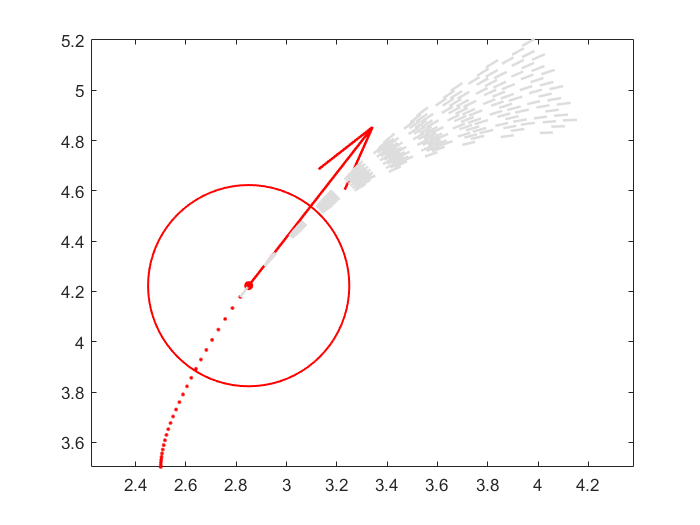

clf;
hold on

% plot grid map
plot_grid(grid_map);
% plot start and goal
plot_square(start, map_size, G, "#f00");
plot_square(goal, map_size, G, "#15c");
% animation
animation = str2func("animation_" + planner_name);
animation(pose, traj, G / 2, record_video);


hold off